Run this mlx at FootHeight folder.

% data = load("deepmimic-H(250mm)-step(10mm).txt");
data = load("deepmimic-H(250mm)-step(20mm).txt");
o_data = load("processed_data_tocabi_walk.txt");

dsp_start = 20600

dsp_start = 20600

dsp_end = 24200

dsp_end = 24200

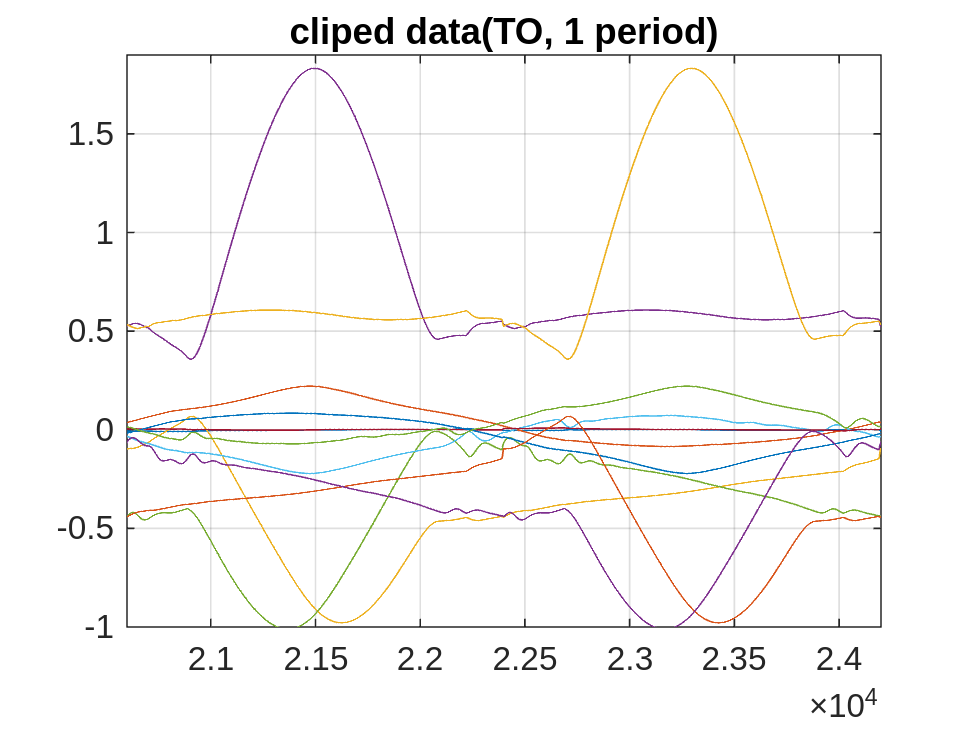

figure(1)
plot(data(:,6:17),'DisplayName','data(:,7:18)')
axis([dsp_start dsp_end -1.0 1.9])
grid on
title('cliped data(TO, 1 period)')

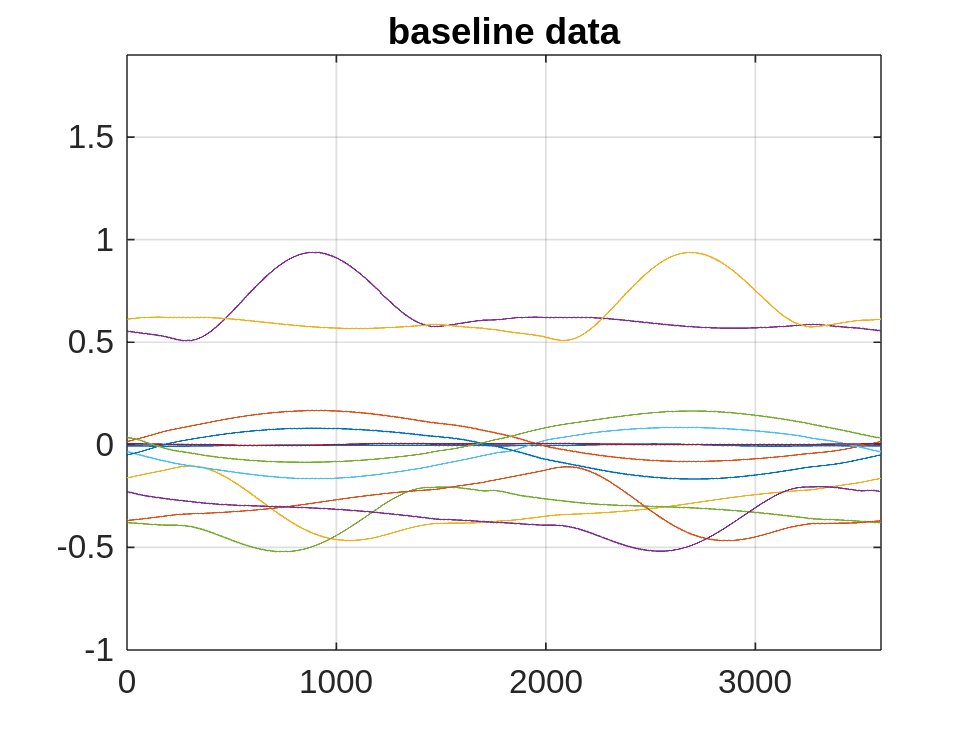


figure(2)
plot(o_data(:,2:13),'DisplayName','o_data(:,3:14)')
axis([0 3600 -1.0 1.9])
grid on
title('baseline data')

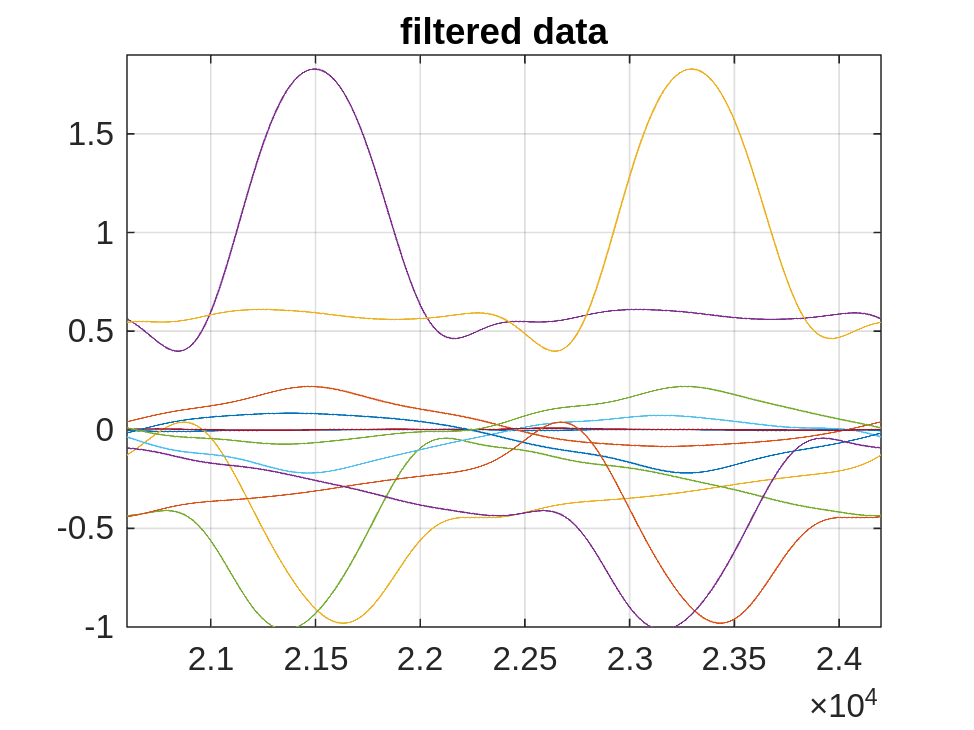

x = data(:, 6:17);
Fs = 2000;
n = 6;
Wn = 4.0;
Fn=Fs/2;
ftype='low';
[b,a] = butter(n,Wn/Fn,ftype);
% y = filter(b,a,x);
y = filtfilt(b, a, x);
plot(y)
axis([dsp_start dsp_end -1.0 1.9])
grid on
title('filtered data')

modify_data = o_data;
modify_data(:,2:13) = y(dsp_start+1:dsp_end, :);
% plot(modify_data(:,3:13),'DisplayName','o_data(:,3:14)')
% axis([0 3600 -1.0 1.9])
% grid on

writematrix(modify_data, 'Output.txt', 'Delimiter','\t');

modify_data_t = modify_data';
save walk_250mm.mat modify_data_t

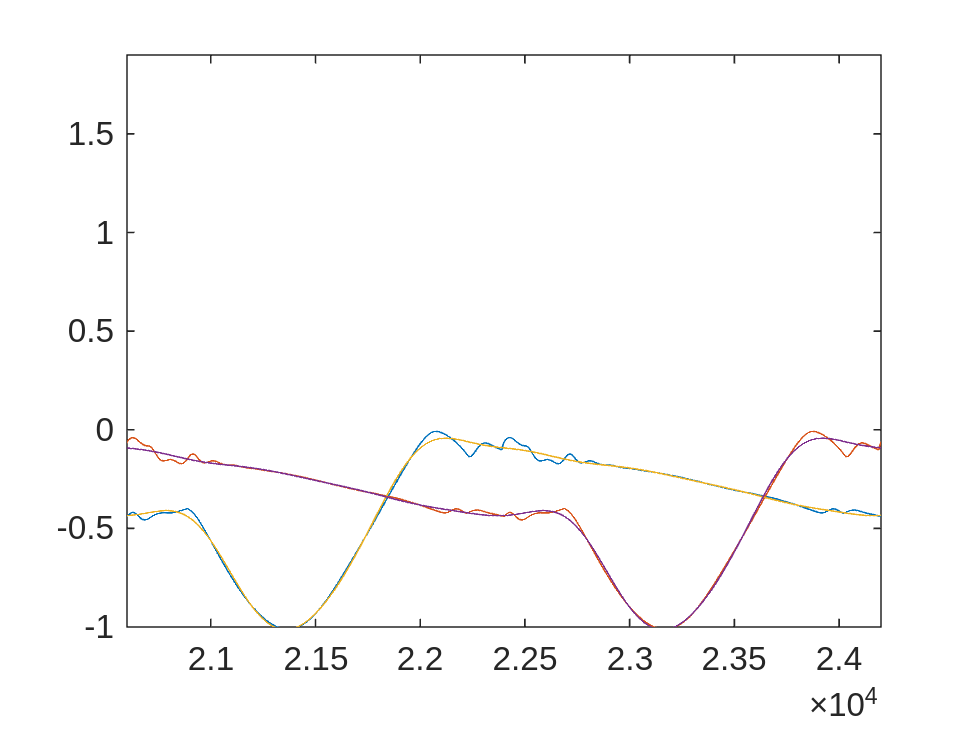

plot(data(:,10))
hold on
plot(data(:,16))
axis([dsp_start dsp_end -1.0 1.9])

x_10 = data(:, 10);
x_16 = data(:, 16);
Wn = 4;
[b,a] = butter(n,Wn/Fn,ftype);
y_10 = filtfilt(b, a, x_10);
y_16 = filtfilt(b, a, x_16);

plot(y_10)
plot(y_16)
axis([dsp_start dsp_end -1.0 1.9])

mean_data = mean(data(dsp_start:dsp_end, 6:17))

mean_data =    -0.0015    0.0401   -0.3902    0.7727   -0.3824   -0.0471    0.0015   -0.0400   -0.3902    0.7727   -0.3823    0.0471


var_data = var(data(dsp_start:dsp_end, 6:17))

var_data =     0.0000    0.0099    0.0663    0.1757    0.0738    0.0086    0.0000    0.0099    0.0663    0.1757    0.0738    0.0086


writematrix(mean_data', 'mean_output.txt');
writematrix(var_data', 'var_output.txt');